% (C) Copyright 2020-2023 Frederico Fernandes Afonso Silva (frederico.silva@ieee.org)
%
%     This file is licensed in the terms of the
%     Attribution-NonCommercial-ShareAlike 4.0 International (CC BY-NC-SA 4.0) 
%     license.
%
% Contributors to this file:
%     Frederico Fernandes Afonso Silva (frederico.silva@ieee.org)
clear all; %#ok
close all;
clc

# Static world (part 1)

## Introduction

Now that we know how to interact with robots in CoppeliaSim, we will start to actuate on the robot through the MATLAB interface. Before we start, however, let us add the namespace to our workspace.

%% Include the DQ Robotics namespace. Probably a good idea to add to all scripts.
include_namespace_dq

Now, let us open the scene [static_world.ttt]. You should see something similar to the image below.

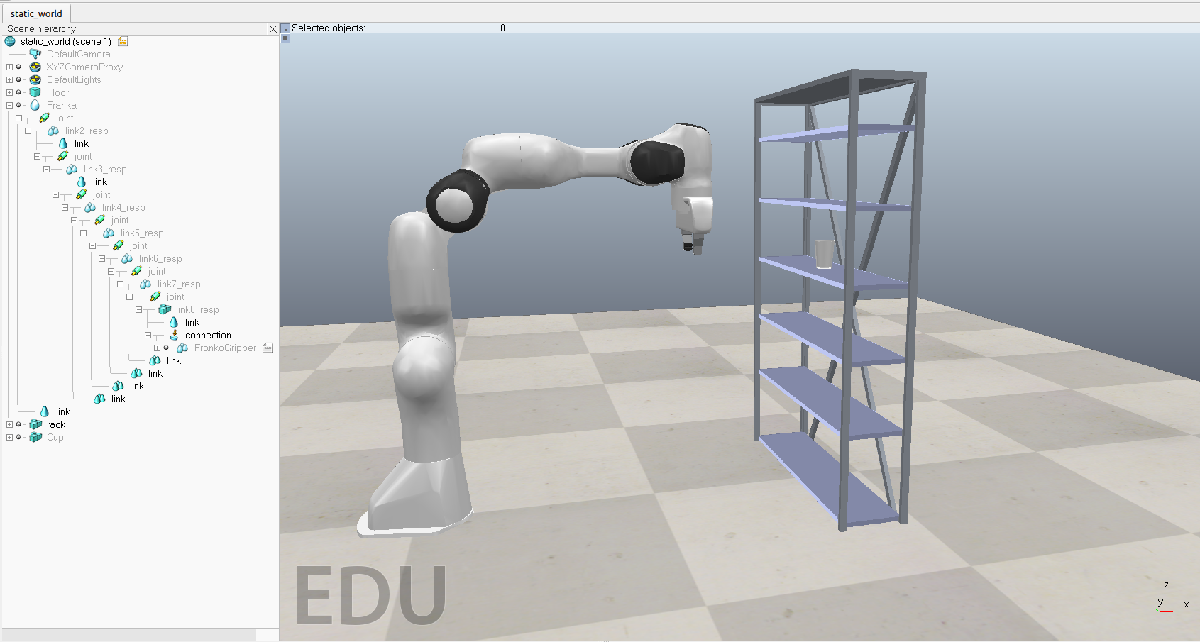

## Communicating with CoppeliaSim

We always have to start by stablishing communication with CoppeliaSim. For this lesson, an asynchronous simulation will suffice. We first creat an 'DQ_VrepInterface' object,

vi = DQ_VrepInterface();

Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)
This version of DQ Robotics DQ_VrepInterface is compatible with VREP 3.5.0


then we break any possible previously existing connection

vi.disconnect_all();

 and stablish a new connection with CoppeliaSim,

vi.connect('127.0.0.1',19997);

Connected to the remote API server


then we stop any simulation that could already be running.

vi.stop_simulation();

Finally, we can now we can start a new asynchronous simulation

vi.start_simulation();

The grayed out 'Start/resume simulation' button, as well as the running clock, indicate that the simulation is currently running (even if the robot/objects aren't moving yet!).

## Sending joint positions to the robot in CoppeliaSim

As discussed in lesson 1, CoppeliaSim has different [joint dynamics properties](https://manual.coppeliarobotics.com/en/jointDynamicsProperties.htm). The Panda robotic manipulator in [static_world.ttt] has its joints set to 'Position' control mode.

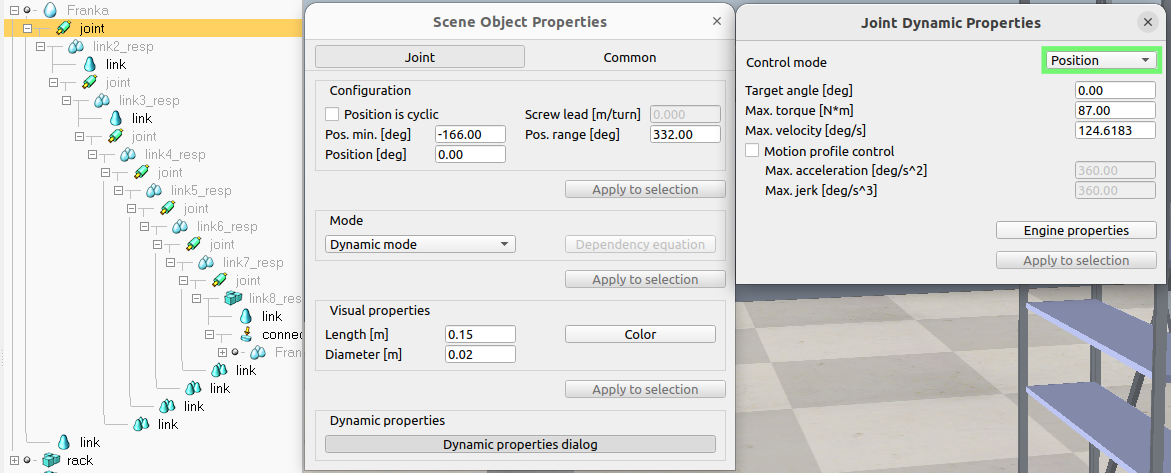

In this operation mode, 'Target angle' defines the desired joint position for the internal joint controller. Each simulation step, the controller will then apply up to the maximum force/torque 'Max. torque', respecting the limit of maximum joint velocity 'Max. velocity', until 'Target angle' is achieved. Through the 'DQ_VrepInterface' we define the desired joint position 'Target angle'.

help vi.set_joint_target_positions

--- help for DQ_VrepInterface/set_joint_target_positions ---

  This method sets the joint target positions of a robot in the CoppeliaSim scene. 
  It is required a dynamics enabled scene, and joints in dynamic mode 
  with position control mode.
 
  Usage:
       Recommended:
       set_joint_target_positions(jointnames,joint_target_positions);
       
       Advanced:
       set_joint_target_positions(jointnames, joint_target_positions, opmode);   
 
           jointnames: The joint names.
           joint_target_positions: The joint target positions.
           (optional) opmode: The operation mode. If not specified, 
                        the opmode will be set automatically. 
                           
                         You can use the following modes:
                            OP_BLOCKING 
                            OP_STREAMING 
                            OP_ONESHOT 
                            OP_BUFFER;
 
       

For instance, we can set the first joint position to $\frac{\pi }{2}$ rad,

jointname={'/Franka/joint'};
q = pi/2;
vi.set_joint_positions(jointnames, q);
%vi.set_joint_target_positions(jointname, q);

which sets the desired configuration of the internal joint controller to $\frac{\pi }{2}$ rad.

## Reading information from CoppeliaSim

'DQ_VrepInterface' allows us to get information about an object's location in the CoppeliaSim scene. For instance, we can get the cup's translation,

vi.get_object_translation('/Cup')

ans =          0.90014i - 0.00012189j + 0.52833k

rotation,

vi.get_object_rotation('/Cup')

ans =          1 + 1.3927e-06i + 4.7843e-06j + 9.0714e-05k

and pose.

vi.get_object_pose('/Cup')

ans =          (1 + 1.4213e-06i + 4.7519e-06j + 9.0711e-05k) + E*( - 2.4602e-05 + 0.45007i - 0.00010153j + 0.26417k)

Since we did not specify any reference frame, all the results above were given with respect to the inertial frame. However, in some situations we might be interested in the cup's pose with respect to a different reference frame. For instance, the end-effector of the Panda robotic manipulator in the scene. We can get this information by defining '/Franka/FrankaGripper' as our reference frame.

vi.get_object_pose('/Cup','/Franka/FrankaGripper', vi.OP_BLOCKING)

ans =          ( - 0.0016525 - 0.0004614i - 1j - 0.00017684k) + E*(0.00022184 + 0.04698i - 4.8914e-05j + 0.15195k)

## Sending commands to CoppeliaSim

Similarly to the use of 'Object/item shift' and 'Object/item rotate', we can move objects in a CoppeliaSim scene using the 'DQ_VrepInterface' class. For instance, we can move the cup to the top shelf

p = 0.900*i_ + 0.82833*k_;
vi.set_object_translation('/Cup', p);

and flip its orientation.

r = cos(pi/2) + i_*sin(pi/2);
vi.set_object_rotation('/Cup', r);

We can also send it back to its original pose on the shelf.

p0 = 0.900*i_ + 0.52833*k_;
x0 = 1 + (1/2)*E_*p0;
vi.set_object_pose('/Cup', x0);

## Finishing communication with CoppeliaSim

After finishing the simulation, we can end the communication with CoppeliaSim.

vi.stop_simulation();
vi.disconnect_all();

## Asynchronous vs synchronous simulation

The simulation performed previously was in asynchronous mode. This means that the simulation was always running, regardless if we interacted with it or not. However, there are situations in which we might want the simulation to only advance when we send some information to CoppeliaSim (e.g., joint control inputs to a robot). This can be accomplished by starting the simulation in synchronous mode

vi.connect('127.0.0.1',19997);

Connected to the remote API server


vi.set_synchronous(true);
vi.start_simulation();

From now until we finish the simulation, it will only advance in time if we give it a trigger. You can see that by noticing that the 'Start/resume simulation' button is grayed out, but the simulation clock is stopped.

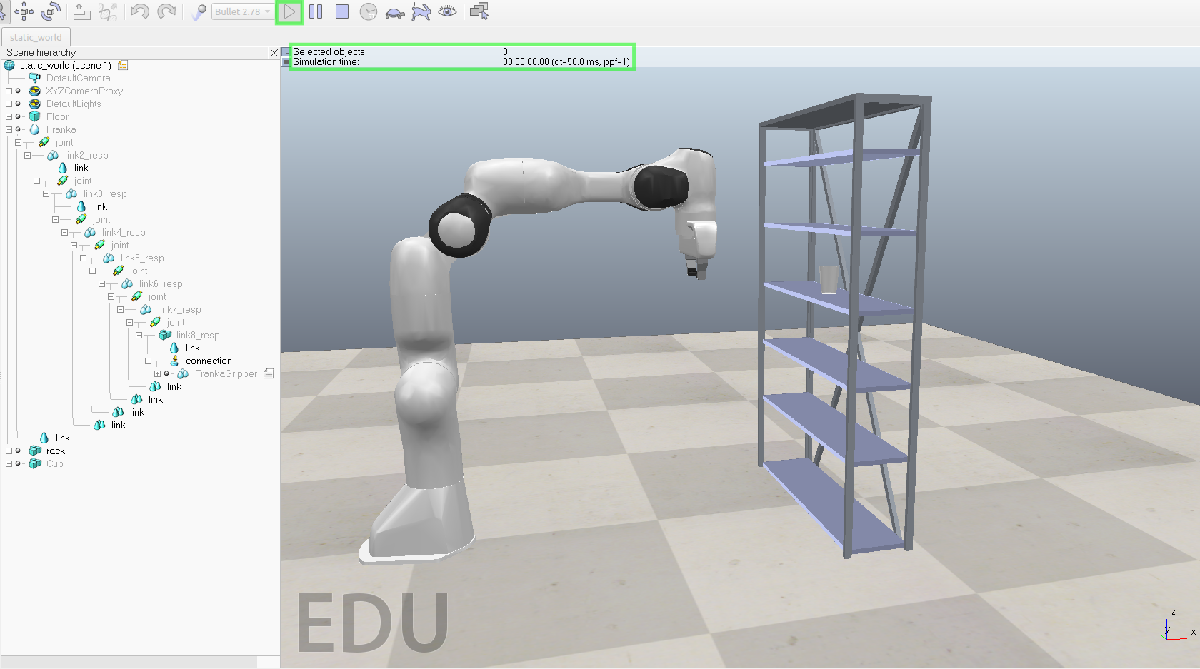

We can remove the cup from the shelf.

p = 0.500*i_ + 0.52833*k_;
vi.set_object_translation('/Cup', p);

Notice that the cup moves even if the simulation is paused.

However, the cup will not fall unless we trigger the simulation.

for i=1:10
    vi.trigger_next_simulation_step();
    vi.wait_for_simulation_step_to_end();
end

We can now finish the simulation again.

vi.stop_simulation();
vi.disconnect_all();

# Homework

- Save the [static_world.ttt] scene as [static_world_part1_homework.ttt] and, in it, do 2-5.

- Read and store the rack's pose.

- Move the rack to position [0.900; 0.200; 0.400].

- Restore the rack to its initial pose.

- Bonus: lay the cup in the bottom shelf.